clear

## **Lista de funções:**

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

## Teste 1 - Função matemática g(x)

Nvar = 2;
Nmax = randi([35,50])
errodf = 15e-2;
NPontosIniciais = randi([8,13])
x_values=[-11;-11]; y_values=[7;7];

PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste1=toc;
xopt_teste1 = minGlobal(Lopt, g);
taxa_media_convergencia_teste1 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste1 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste1, minimizantes_locais_teste1] = minimosMinimizantesLocais(Lopt, g);

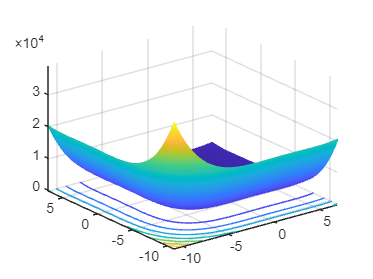

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

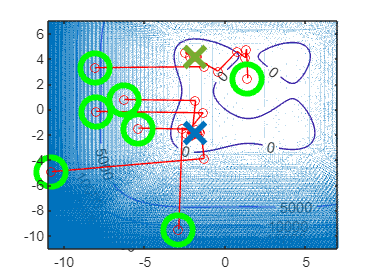


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2- Função de Rosenbrock

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(r, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2=toc;
xopt_teste2 = minGlobal(Lopt, r);
taxa_media_convergencia_teste2 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste2 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste2, minimizantes_locais_teste2] = minimosMinimizantesLocais(Lopt, r);

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

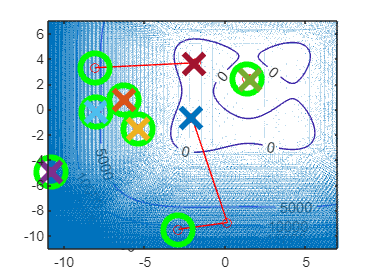


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3- Função matemática f(x)

tic;
[Lista, LNit, Lopt, dffinal] = steepest_descent_wolfe(f, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3= toc;
xopt_teste3 = minGlobal(Lopt, f);
taxa_media_convergencia_teste3 = taxaMediaConvergencia(LNit);
tipo_convergencia_teste3 = tipoConvergencia(dffinal, errodf, Nmax);
[minimos_locais_teste3, minimizantes_locais_teste3] = minimosMinimizantesLocais(Lopt, f);

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

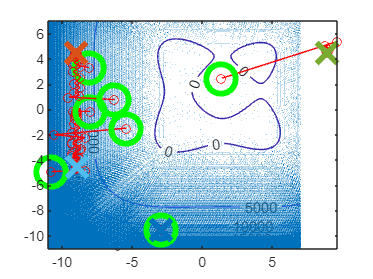


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

tempo_execucao = {tempo_execucao_teste1, tempo_execucao_teste2, tempo_execucao_teste3};
taxa_media_convergencia = {taxa_media_convergencia_teste1, taxa_media_convergencia_teste2, taxa_media_convergencia_teste3};

T = table(tempo_execucao', taxa_media_convergencia');

disp(T);

        Var1           Var2   
    ____________    __________

    {[  1.8530]}    {[7.8571]}
    {[189.7237]}    {[    50]}
    {[ 45.0028]}    {[    29]}

